# Clipping and Hidden Surface Determination Exercises

[Link to lecture notes](https://jonshiach.github.io/graphics-book/files/4.6_Clipping_and_HSD_exercises.html)

### Exercise 21

Use the Cyrus-Beck algorithm to clip the lines $\mathbf{a} \to \mathbf{b}$, $\mathbf{c} \to \mathbf{d}$ and $\mathbf{e} \to \mathbf{f}$ to the visible region shown in the diagram below.

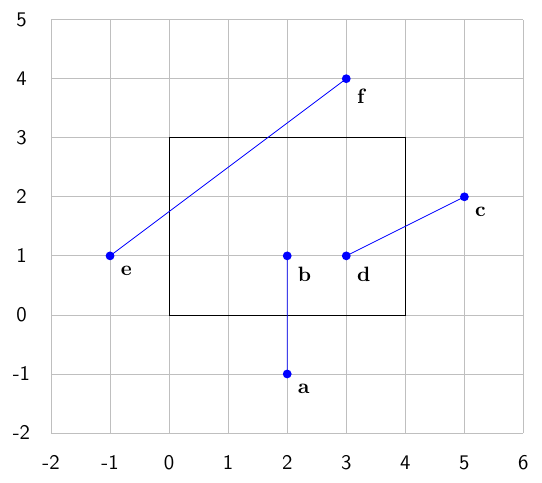

a = [2 ; -1];
b = [2 ; 1];
c = [5 ; 2];
d = [3 ; 1];
e = [-1 ; 1];
f = [3 ; 4];

n = [ 0, -1,  0,  1 ;
      1,  0, -1,  0 ];
p = [ 0,  4,  4,  0 ;
      0,  3,  3,  0 ];

Line $\mathbf{a} \to \mathbf{b}$: clip to bottom edge

da = dot(a - p(:,1), n(:,1))

da = -1

db = dot(b - p(:,1), n(:,1))

db = 1

$d(\mathbf{a}) < 0$ and $d(\mathbf{b})>0$ so clip $\mathbf{a}$ to bottom edge

t = sym(da / (da - db))

$$t = \frac{1}{2}$$

a = a + t * (b - a)

$$a = \left(\begin{array}{c} 2\\ 0 \end{array}\right)$$

Line $\mathbf{c} \to \mathbf{d}$: clip to right edge

dc = dot(c - p(:,2), n(:,2))

dc = -1

dd = dot(d - p(:,2), n(:,2))

dd = 1

t = sym(dc / (dc - dd))

$$t = \frac{1}{2}$$

d = c + t * (d - c)

$$d = \left(\begin{array}{c} 4\\ \frac{3}{2} \end{array}\right)$$

Line $\mathbf{e} \to \mathbf{f}$: clip to top edge

de = dot(e - p(:,3), n(:,3))

de = 2

df = dot(f - p(:,3), n(:,3))

df = -1

$d(\mathbf{e}) > 0$ and $d(\mathbf{f}) < 0$ so clip $\mathbf{f}$ to top edge.

t = sym(de / (de - df))

$$t = \frac{2}{3}$$

f = e + t * (f - e)

$$f = \left(\begin{array}{c} \frac{5}{3}\\ 3 \end{array}\right)$$

Clip to left edge

de = dot(e - p(:,4), n(:,4))

de = -1

df = dot(f - p(:, 4), n(:,4))

$$df = \frac{5}{3}$$

$d(\mathbf{e}) < 0$ and $d(\mathbf{f}) > 0$ so clip $\mathbf{e}$ to left edge

t = sym(de / (de - df))

$$t = \frac{3}{8}$$

e = e + t * (f - e)

$$e = \left(\begin{array}{c} 0\\ \frac{7}{4} \end{array}\right)$$

### Exercise 23

clear

% Define tetrahedron 
V = [  1,  2,  0,  1 ;
       1,  2,  3,  0 ;
      -7, -6, -5, -4 ;
       1,  1,  1,  1 ];
F = [ 3, 2, 1 ;
      2, 3, 4 ; 
      1, 2, 4 ;
      3, 1, 4 ];

% Define viewing position
p = [ 0 ; 0 ; 0 ];

% Loop through faces and determine whether they are front or back facign
for i = 1 : 4
    n = sym(cross(V(1:3,F(i,2)) - V(1:3,F(i,1)), V(1:3,F(i,3)) - V(1:3,F(i,2))))
    ndotv = dot(n, V(1:3,F(i,1)) - p)
end

$$n = \left(\begin{array}{c} 0\\ 3\\ -3 \end{array}\right)$$

$$ndotv = 24$$

$$n = \left(\begin{array}{c} 4\\ 3\\ 5 \end{array}\right)$$

$$ndotv = -16$$

$$n = \left(\begin{array}{c} 4\\ -3\\ -1 \end{array}\right)$$

$$ndotv = 8$$

$$n = \left(\begin{array}{c} -8\\ -3\\ -1 \end{array}\right)$$

$$ndotv = -4$$